clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
vignette=double(rgb2gray(imread('viñeta2.jpg')));
vignette=vignette./max(vignette(:));

RGB = imread(string(fullfile(img_path, T{586,1})));

Ig=rgb2gray(RGB);

Creo un contour

thres=Ig>8;
se = strel('disk',100);
thres_eroded=imerode(thres,se);
contour=thres-thres_eroded;

figure;

imshow(thres);

figure;

imshow(thres_eroded);

figure;

imshow(contour);

title('contour')

Divido el contour en izquierda y derecha porque el quemado suele estar solo en uno de los lados

[filas, columnas, ~] = size(contour);
mitad_derecha_negra = contour(:, floor(columnas/2) + 1:end, :);
mitad_derecha_negra(:) = 0;
contour_izquierda = cat(2, contour(:, 1:floor(columnas/2), :), mitad_derecha_negra);

imshow(contour_izquierda);

title('contour izq.')


mitad_izquierda_negra = contour(:, 1:floor(columnas/2), :);
mitad_izquierda_negra(:) = 0;
contour_derecha = cat(2, mitad_izquierda_negra, contour(:, floor(columnas/2) + 1:end, :));

imshow(contour_derecha);

title('contour dcha.')

Multiplico las plantillas de contour por la imagen original

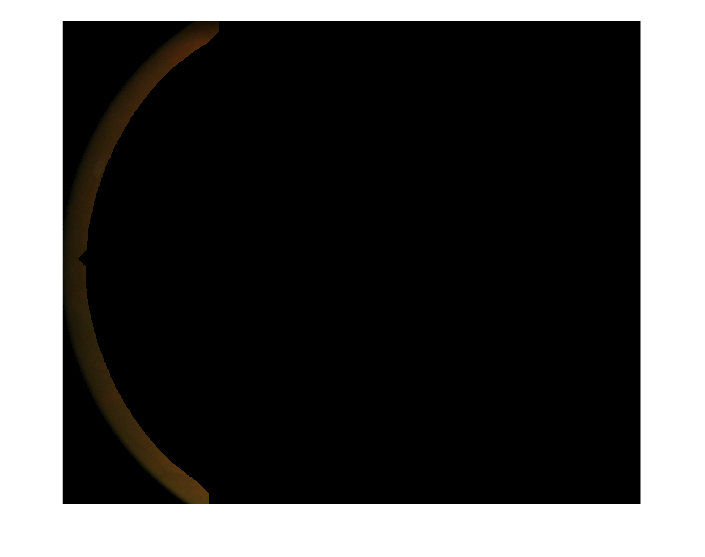

RGB=double(RGB);
plantilla_izquierda=RGB.*contour_izquierda;
plantilla_izquierda=uint8(plantilla_izquierda);
figure;
imshow(plantilla_izquierda);

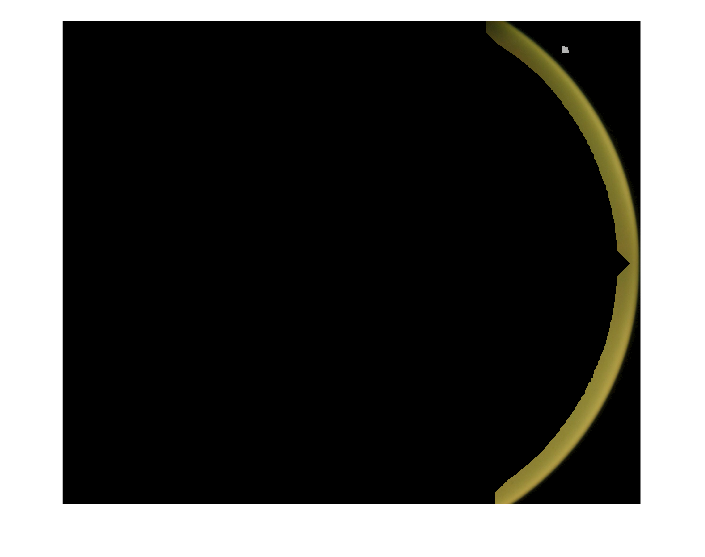

%lo mismo pa la derecha
plantilla_derecha=RGB.*contour_derecha;
plantilla_derecha=uint8(plantilla_derecha);
figure;
imshow(plantilla_derecha);

Calculo la media en cada plantilla. Si da más de 100 es sospechoso de que está quemado.

elementosNoCero_izquierda = nonzeros(plantilla_izquierda);
suma_izquierda = sum(elementosNoCero_izquierda);
media_izquierda = mean(elementosNoCero_izquierda);

elementosNoCero_derecha = nonzeros(plantilla_derecha);
suma_derecha = sum(elementosNoCero_derecha);
media_derecha = mean(elementosNoCero_derecha);

Ahora escribo un if para que añada un efecto viñeta a las imágenes quemadas

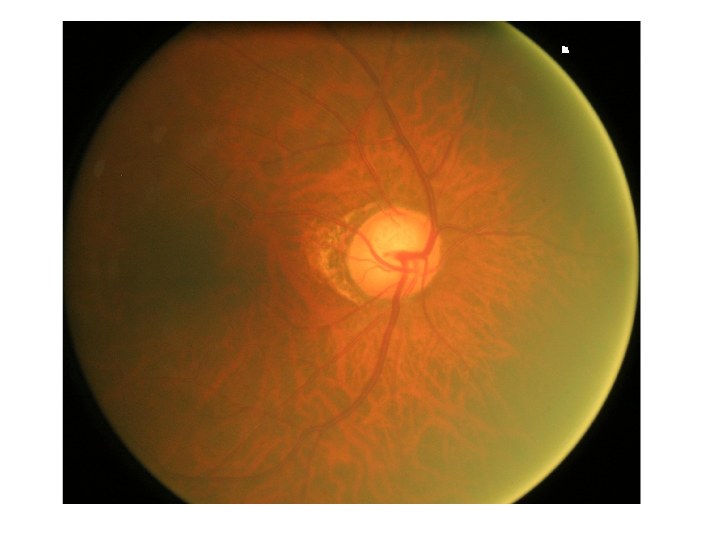

[alto_original, ancho_original, ~] = size(RGB);
vignette_redimensioned = imresize(vignette, [alto_original, ancho_original]);
vignette_redimensioned=vignette_redimensioned./max(vignette_redimensioned(:));
vignette_redimensioned=vignette_redimensioned.^0.2;%segun la berreketa que pongas aquí se va a oscurecer más. Elije un valor entre 0 y 1
vignette_redimensioned=vignette_redimensioned./max(vignette_redimensioned(:));
RGB_sinQuemado=RGB.*vignette_redimensioned;
RGB_sinQuemado=uint8(RGB_sinQuemado);
imshow(uint8(RGB))

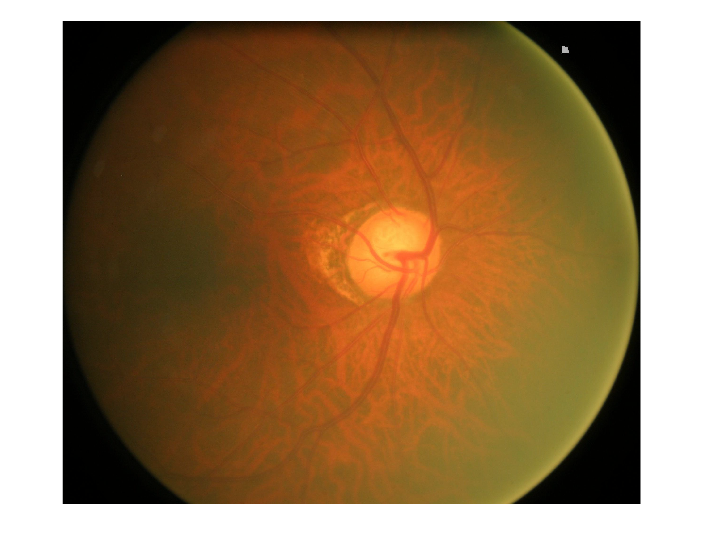

imshow(RGB_sinQuemado);